## This exercise is a group effort by me, Keyhan Rayati , Mohammad Oladian

## Questions:

**(a)** although *filter()* and *filtfilt()* both remove the high frequency noise, the use of *filter()* introduces significant phase delay. *filtfilt()* has zero phase delay. Furthermore, at t=0, the output of filter() starts at 0, whereas the output of filtfilt() has matched the initial conditions exactly. *filtfilt *performs zero-phase digital filtering. We need the phase value which is retrieved by the Hilbert transform So we should use *filter() *to not lose the phase value.

**(b) **In practice, the value of a PLV obtained is going to vary very little over time and the absolute PLV is not what we are interested in. We are interested in knowing whether an experimental stimulus induced a change in PLV. Here, we want to answer the question: "was there an increased connectivity between *'V4'* and *'FEF' *electrodes when a trained Macaque monkey is performing a memory-guided-saccade (MGS)  task?". we should test if PLV after stimulus is significantly greater than the PLV before stimulus. So, we use the pre-stimulus period as a baseline and perform a z-transform normalization.

**(c)** No, 

**(d)**

close all;
clear;
clc;

#### Loading the dataset

load('lfp.mat');
V4 = 1;
FEF = 2;

#### **defining frequency & bandwidth**

fs=1000;
ws=2*pi*fs;

f_delta=[0.5 4];
w_delta=2*pi*f_delta;
f_theta=[4 8];
w_theta=2*pi*f_theta;
f_alpha=[8 13];
w_alpha=2*pi*f_alpha;
f_beta=[13 30];
w_beta=2*pi*f_beta;
f_gamma=[30 60];
w_gamma=2*pi*f_gamma;

delta_band=w_delta/ws;
theta_band=w_theta/ws;
alpha_band=w_alpha/ws;
beta_band=w_beta/ws;
gamma_band=w_gamma/ws;

#### Signal Plots for trial 1 before filtering

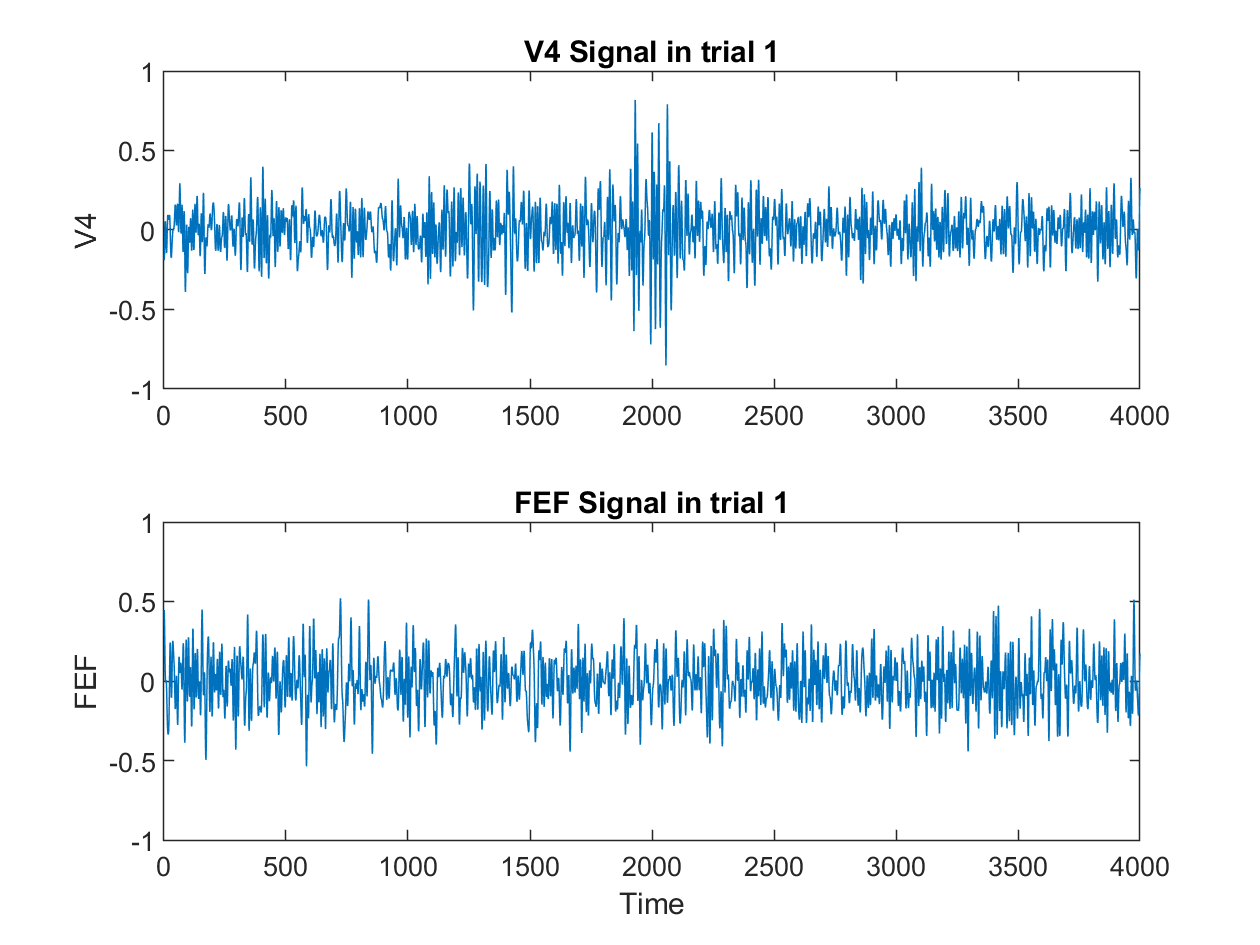

tiledlayout(2,1)

% Top plot
ax1 = nexttile;
plot(ax1,X_in_sessions(V4,:,1))
title(ax1,'V4 Signal in trial 1')
ylabel(ax1,'V4')
ylim([-1 1])

% Bottom plot
ax2 = nexttile;
plot(ax2,X_in_sessions(FEF,:,1))
title(ax2,'FEF Signal in trial 1')
ylabel(ax2,'FEF')
xlabel(ax2, 'Time')
ylim([-1 1])

#### Hamming window to calculate each frequency band with 100th order

order = 100;
delta = fir1(order,[delta_band]);
theta = fir1(order,[theta_band]);
alpha = fir1(order,[alpha_band]);
beta = fir1(order,[beta_band]);
gamma = fir1(order,[gamma_band]);

### Step1) Filtering the V4 and FEF signals with *filter()* Function for delta, theta, alpha, beta, gamma

cnt_trial = length(X_in_sessions(1,1,:));
time = length(X_in_sessions(1,:,1));

%filtering the V4 signal for each trial
for i = 1:cnt_trial
    x = X_in_sessions(V4,:,i);
    V4_filt_delta(i,:) = filter(delta,1,x);
    V4_filt_theta(i,:) = filter(theta,1,x);
    V4_filt_alpha(i,:) = filter(alpha,1,x);
    V4_filt_beta(i,:) = filter(beta,1,x);
    V4_filt_gamma(i,:) = filter(gamma,1,x);
end

%filtering the V4 signal for each trial
for i = 1:cnt_trial
    x = X_in_sessions(FEF,:,i);
    FEF_filt_delta(i,:) = filter(delta,1,x);
    FEF_filt_theta(i,:) = filter(theta,1,x);
    FEF_filt_alpha(i,:) = filter(alpha,1,x);
    FEF_filt_beta(i,:) = filter(beta,1,x);
    FEF_filt_gamma(i,:) = filter(gamma,1,x);
end

#### Signal Plots for trial 1 after filtering with *filter() *for *delta* band

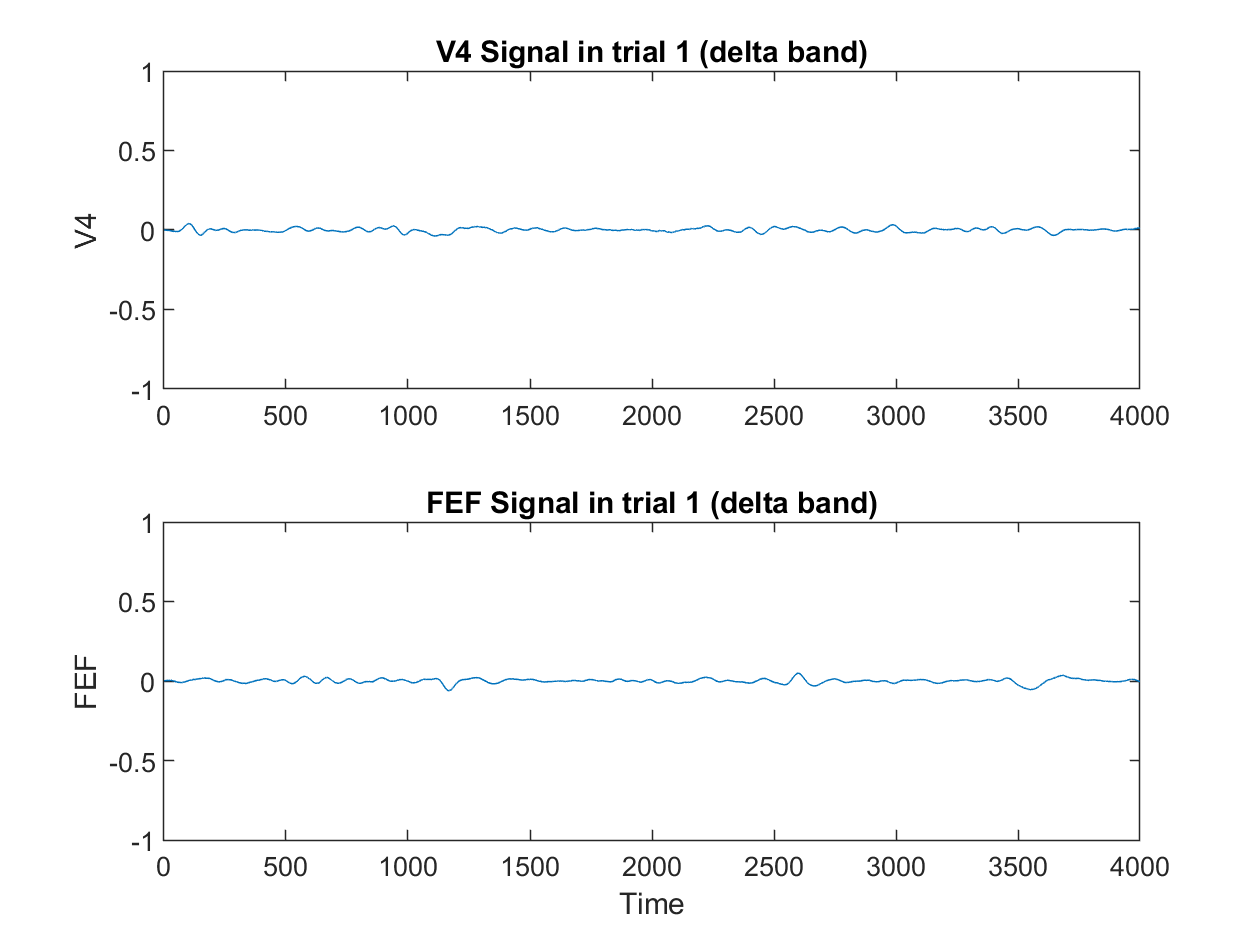

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,V4_filt_delta(1,:));
title(ax1,'V4 Signal in trial 1 (delta band)');
ylabel(ax1,'V4');
ylim([-1 1]);

% Bottom plot
ax2 = nexttile;
plot(ax2,FEF_filt_delta(1,:));
title(ax2,'FEF Signal in trial 1 (delta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');
ylim([-1 1]);

#### Signal Plots for trial 1 after filtering with *filter() *for *theta* band

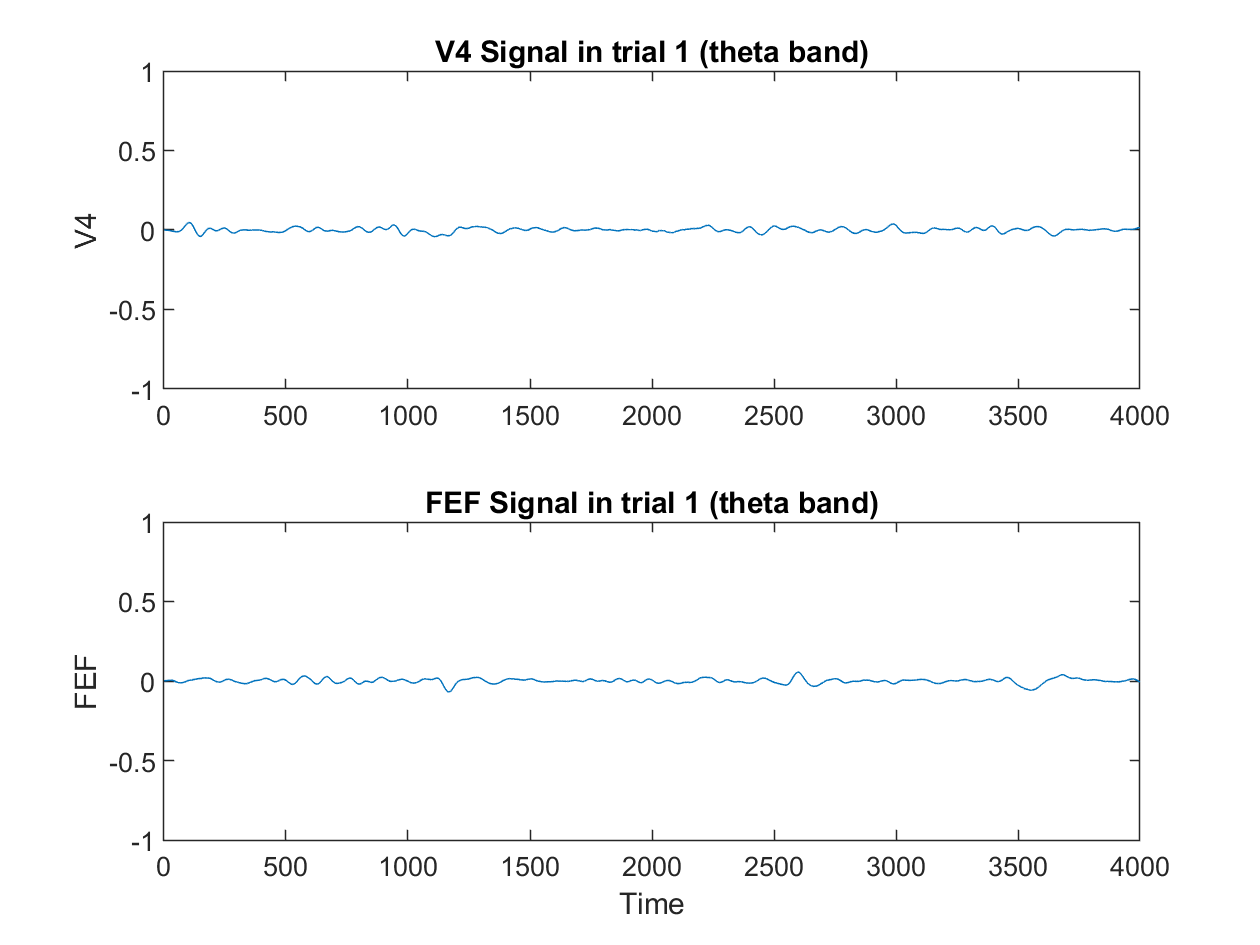

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,V4_filt_theta(1,:));
title(ax1,'V4 Signal in trial 1 (theta band)');
ylabel(ax1,'V4');
ylim([-1 1]);

% Bottom plot
ax2 = nexttile;
plot(ax2,FEF_filt_theta(1,:));
title(ax2,'FEF Signal in trial 1 (theta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');
ylim([-1 1]);

#### Signal Plots for trial 1 after filtering with *filter() *for *alpha* band

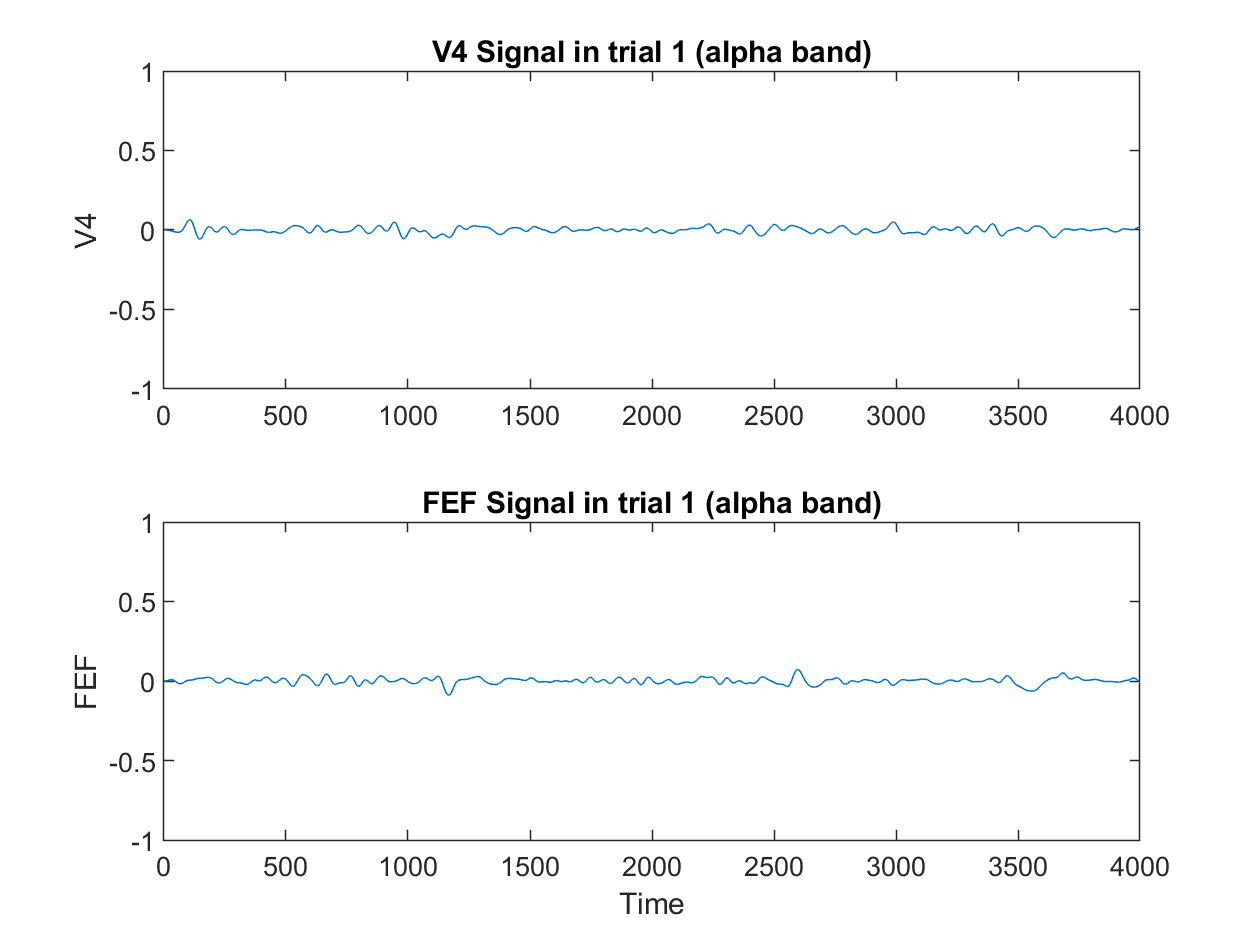

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,V4_filt_alpha(1,:));
title(ax1,'V4 Signal in trial 1 (alpha band)');
ylabel(ax1,'V4');
ylim([-1 1]);

% Bottom plot
ax2 = nexttile;
plot(ax2,FEF_filt_alpha(1,:));
title(ax2,'FEF Signal in trial 1 (alpha band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');
ylim([-1 1]);

#### Signal Plots for trial 1 after filtering with *filter() *for *beta* band

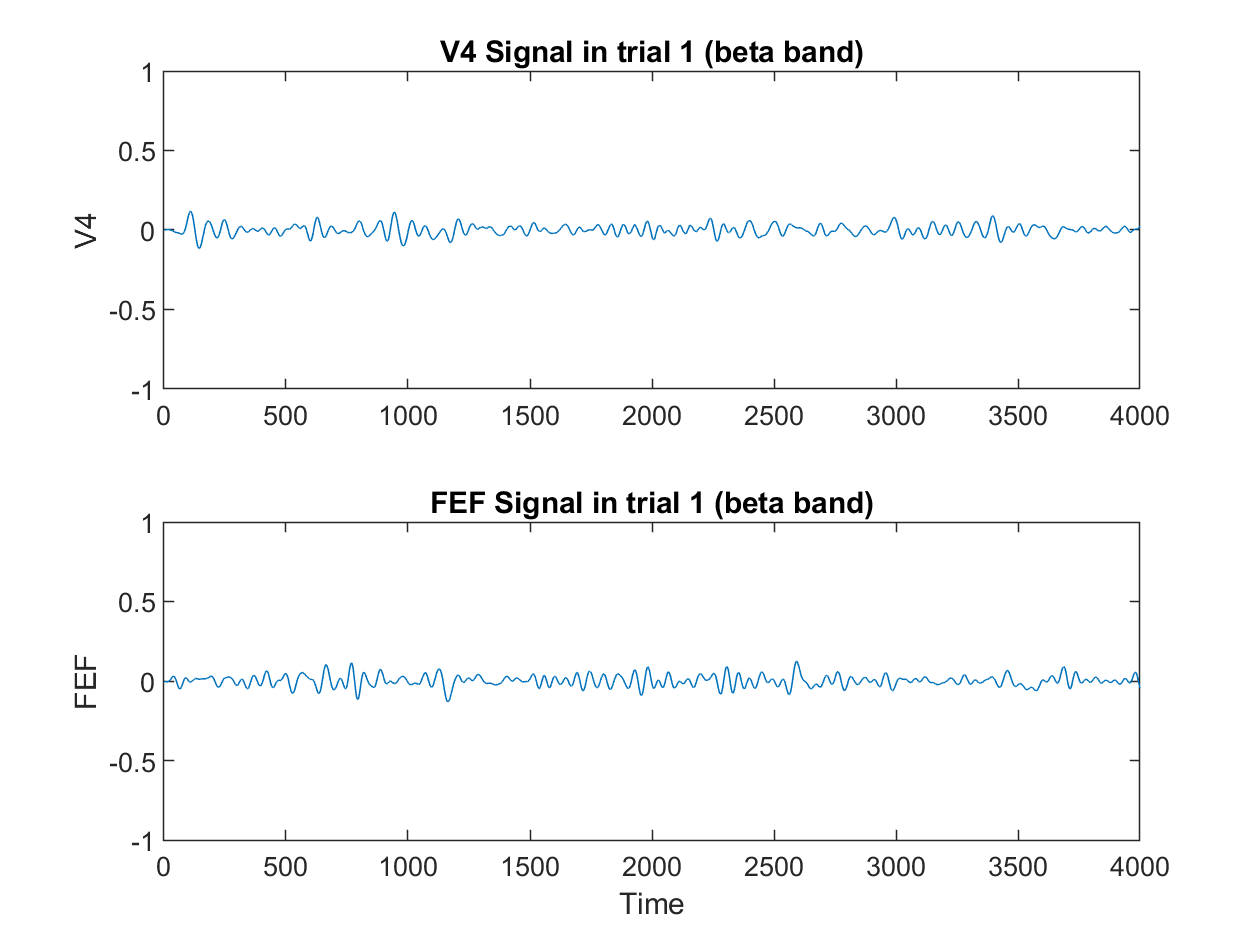

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,V4_filt_beta(1,:));
title(ax1,'V4 Signal in trial 1 (beta band)');
ylabel(ax1,'V4');
ylim([-1 1]);

% Bottom plot
ax2 = nexttile;
plot(ax2,FEF_filt_beta(1,:));
title(ax2,'FEF Signal in trial 1 (beta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');
ylim([-1 1]);

#### Signal Plots for trial 1 after filtering with *filter() *for *gamma* band

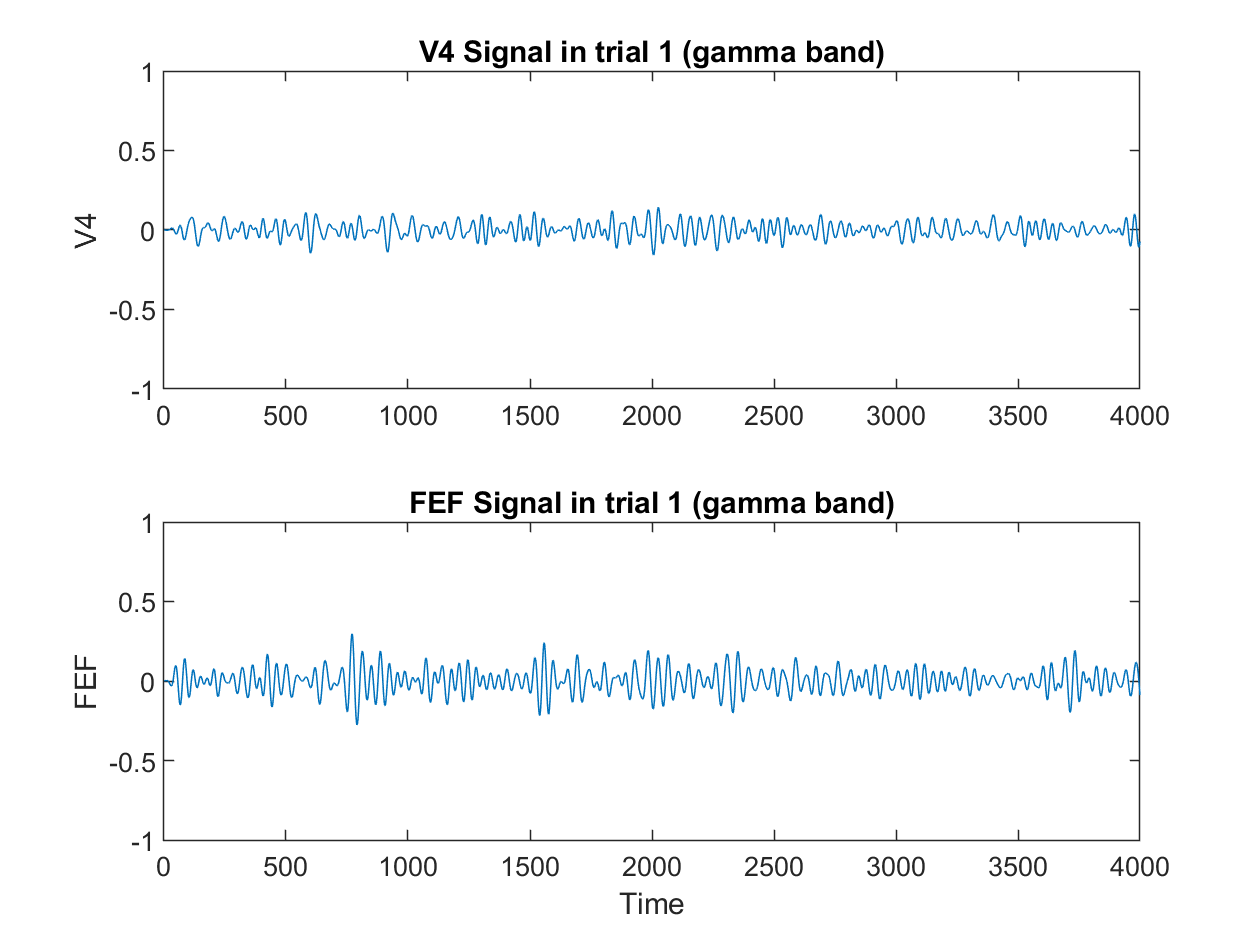

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,V4_filt_gamma(1,:));
title(ax1,'V4 Signal in trial 1 (gamma band)');
ylabel(ax1,'V4');
ylim([-1 1]);

% Bottom plot
ax2 = nexttile;
plot(ax2,FEF_filt_gamma(1,:));
title(ax2,'FEF Signal in trial 1 (gamma band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');
ylim([-1 1]);

### Step 2) Hilbert Transform

%filtering the V4 signal for each trial
for i = 1:cnt_trial
    Hilbert_V4_delta(i,:)=hilbert(V4_filt_delta(i,:));
    Hilbert_V4_theta(i,:)=hilbert(V4_filt_theta(i,:));
    Hilbert_V4_alpha(i,:)=hilbert(V4_filt_alpha(i,:));
    Hilbert_V4_beta(i,:)=hilbert(V4_filt_beta(i,:));
    Hilbert_V4_gamma(i,:)=hilbert(V4_filt_gamma(i,:));
    for j=1:time
        PhaseAng_V4_delta(i,j)=atan(imag(Hilbert_V4_delta(i,j)/(real(Hilbert_V4_delta(i,j)))));
        PhaseAng_V4_theta(i,j)=atan(imag(Hilbert_V4_theta(i,j)/(real(Hilbert_V4_theta(i,j)))));
        PhaseAng_V4_alpha(i,j)=atan(imag(Hilbert_V4_alpha(i,j)/(real(Hilbert_V4_alpha(i,j)))));
        PhaseAng_V4_beta(i,j)=atan(imag(Hilbert_V4_beta(i,j)/(real(Hilbert_V4_beta(i,j)))));
        PhaseAng_V4_gamma(i,j)=atan(imag(Hilbert_V4_gamma(i,j)/(real(Hilbert_V4_gamma(i,j)))));
    end
end
%filtering the FEF signal for each trial
for i = 1:cnt_trial
    Hilbert_FEF_delta(i,:)=hilbert(FEF_filt_delta(i,:));
    Hilbert_FEF_theta(i,:)=hilbert(FEF_filt_theta(i,:));
    Hilbert_FEF_alpha(i,:)=hilbert(FEF_filt_alpha(i,:));
    Hilbert_FEF_beta(i,:)=hilbert(FEF_filt_beta(i,:));
    Hilbert_FEF_gamma(i,:)=hilbert(FEF_filt_gamma(i,:));
    for j=1:time
        PhaseAng_FEF_delta(i,j)=atan(imag(Hilbert_FEF_delta(i,j)/(real(Hilbert_FEF_delta(i,j)))));
        PhaseAng_FEF_theta(i,j)=atan(imag(Hilbert_FEF_theta(i,j)/(real(Hilbert_FEF_theta(i,j)))));
        PhaseAng_FEF_alpha(i,j)=atan(imag(Hilbert_FEF_alpha(i,j)/(real(Hilbert_FEF_alpha(i,j)))));
        PhaseAng_FEF_beta(i,j)=atan(imag(Hilbert_FEF_beta(i,j)/(real(Hilbert_FEF_beta(i,j)))));
        PhaseAng_FEF_gamma(i,j)=atan(imag(Hilbert_FEF_gamma(i,j)/(real(Hilbert_FEF_gamma(i,j)))));
    end
end

clear i;

#### Phase plot of each signal in trial 1 after Hilbert Transform for delta band

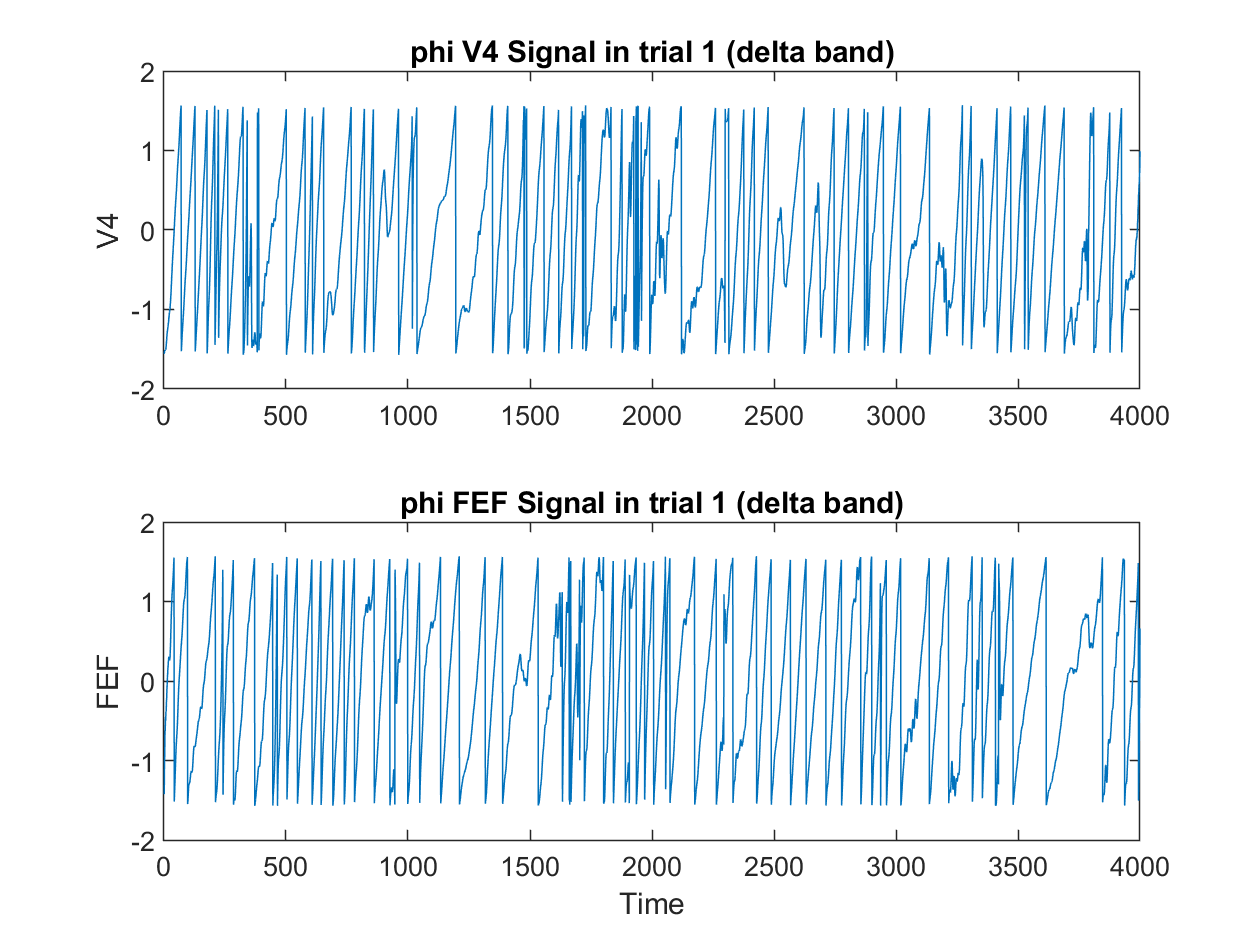

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,PhaseAng_V4_delta(1,:));
title(ax1,'phi V4 Signal in trial 1 (delta band)');
ylabel(ax1,'V4');


% Bottom plot
ax2 = nexttile;
plot(ax2,PhaseAng_FEF_delta(1,:));
title(ax2,'phi FEF Signal in trial 1 (delta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');

#### Phase plot of each signal in trial 1 after Hilbert Transform for theta band

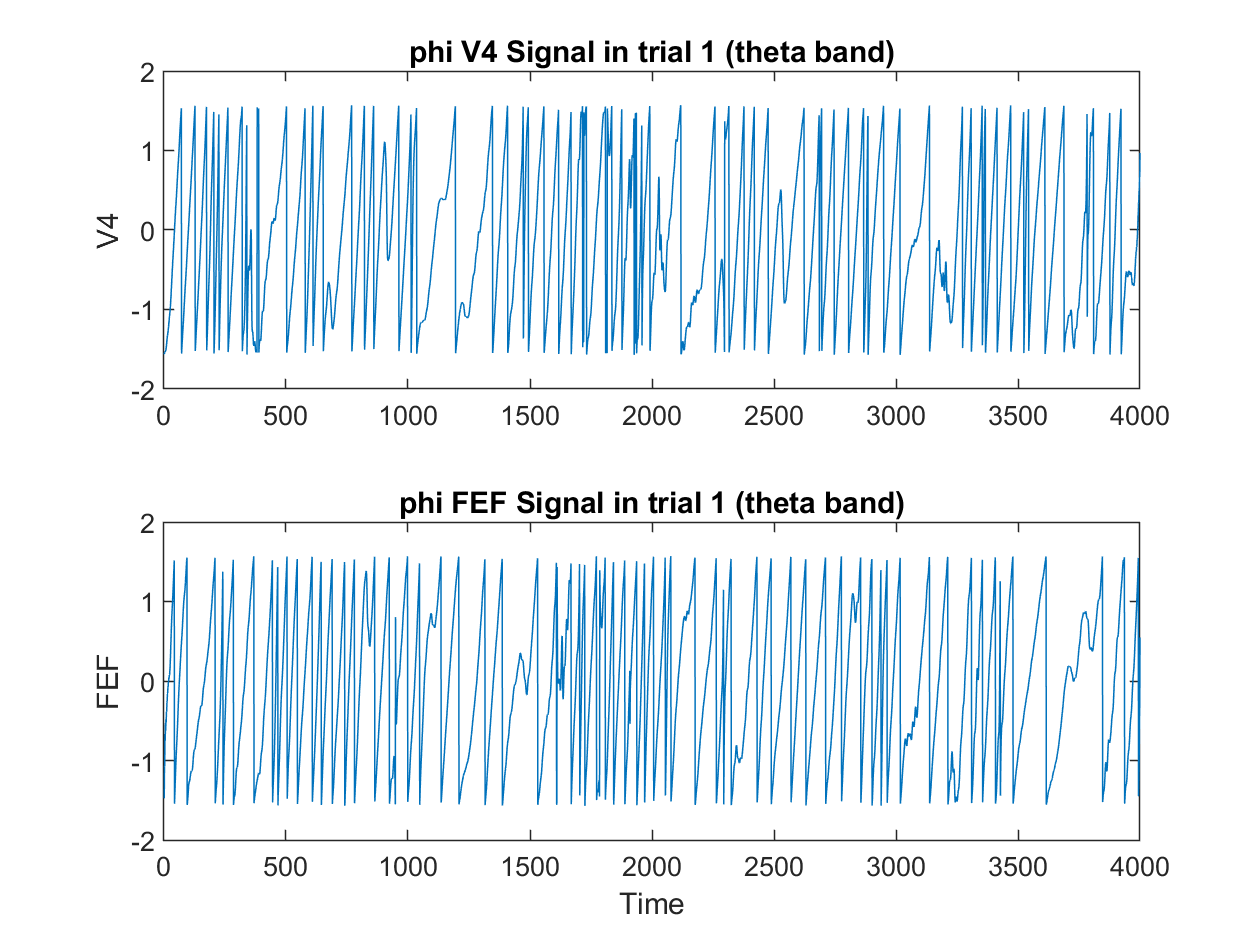

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,PhaseAng_V4_theta(1,:));
title(ax1,'phi V4 Signal in trial 1 (theta band)');
ylabel(ax1,'V4');


% Bottom plot
ax2 = nexttile;
plot(ax2,PhaseAng_FEF_theta(1,:));
title(ax2,'phi FEF Signal in trial 1 (theta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');

#### Phase plot of each signal in trial 1 after Hilbert Transform for alpha band

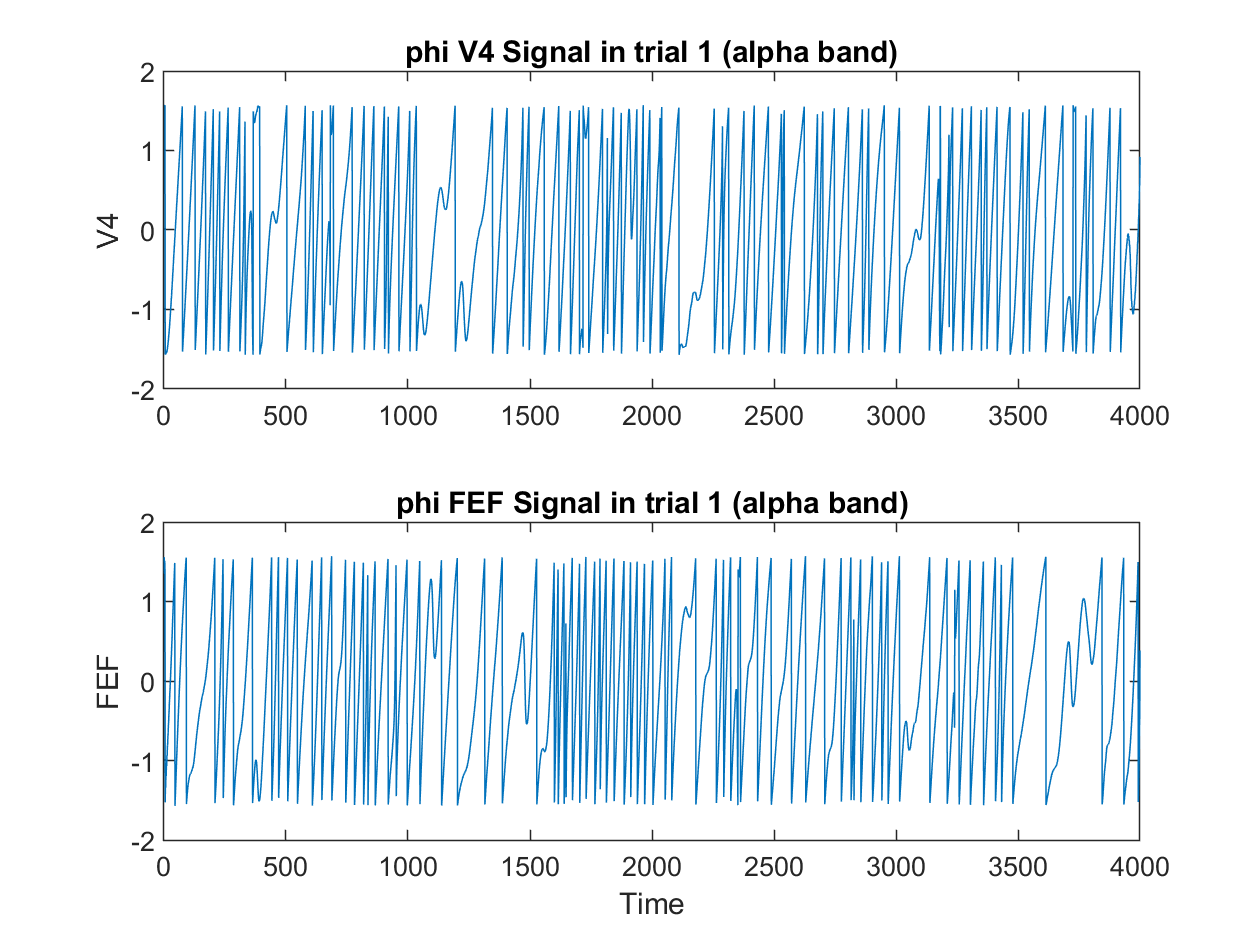

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,PhaseAng_V4_alpha(1,:));
title(ax1,'phi V4 Signal in trial 1 (alpha band)');
ylabel(ax1,'V4');


% Bottom plot
ax2 = nexttile;
plot(ax2,PhaseAng_FEF_alpha(1,:));
title(ax2,'phi FEF Signal in trial 1 (alpha band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');

#### Phase plot of each signal in trial 1 after Hilbert Transform for beta band

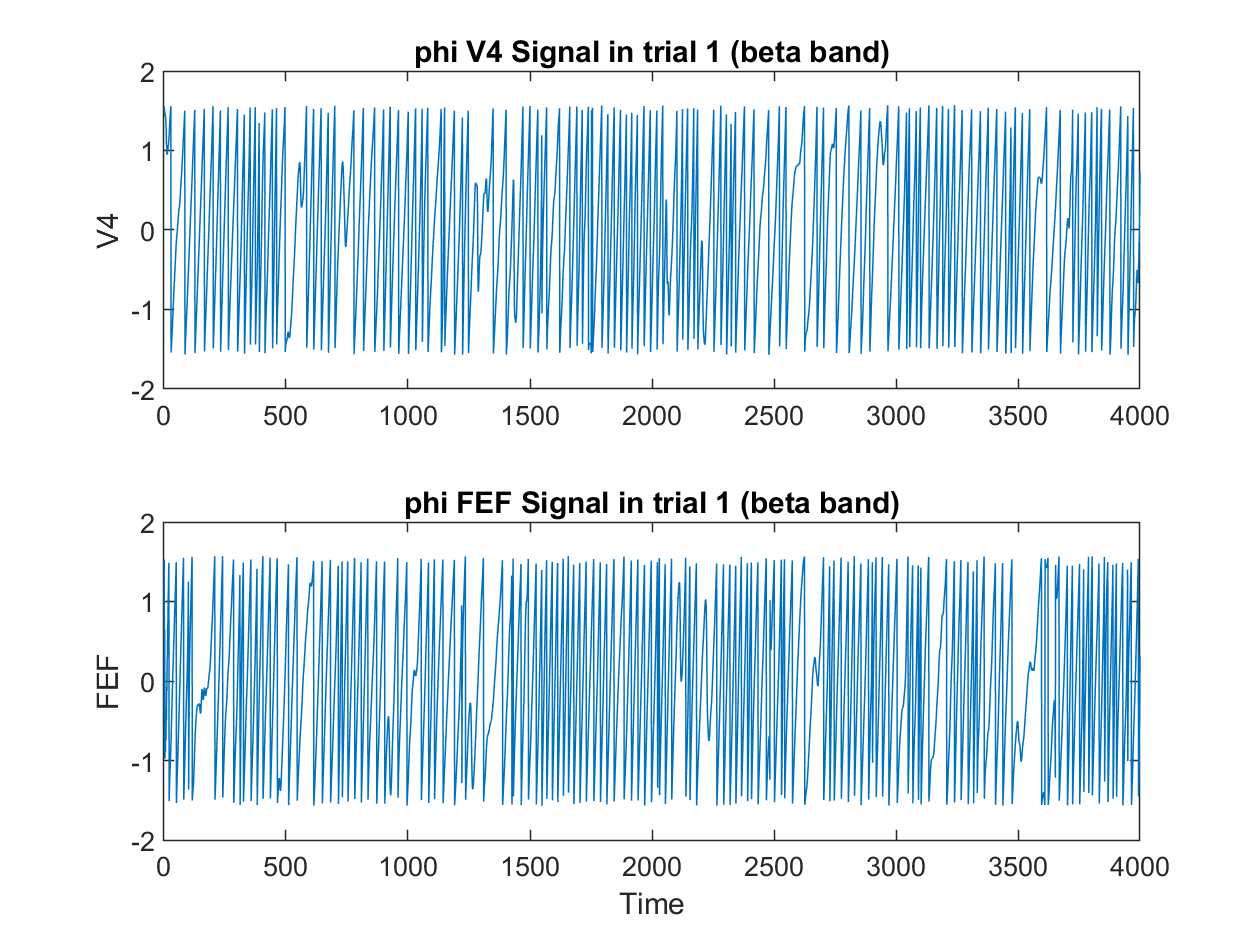

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,PhaseAng_V4_beta(1,:));
title(ax1,'phi V4 Signal in trial 1 (beta band)');
ylabel(ax1,'V4');


% Bottom plot
ax2 = nexttile;
plot(ax2,PhaseAng_FEF_beta(1,:));
title(ax2,'phi FEF Signal in trial 1 (beta band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');

#### Phase plot of each signal in trial 1 after Hilbert Transform for gamma band

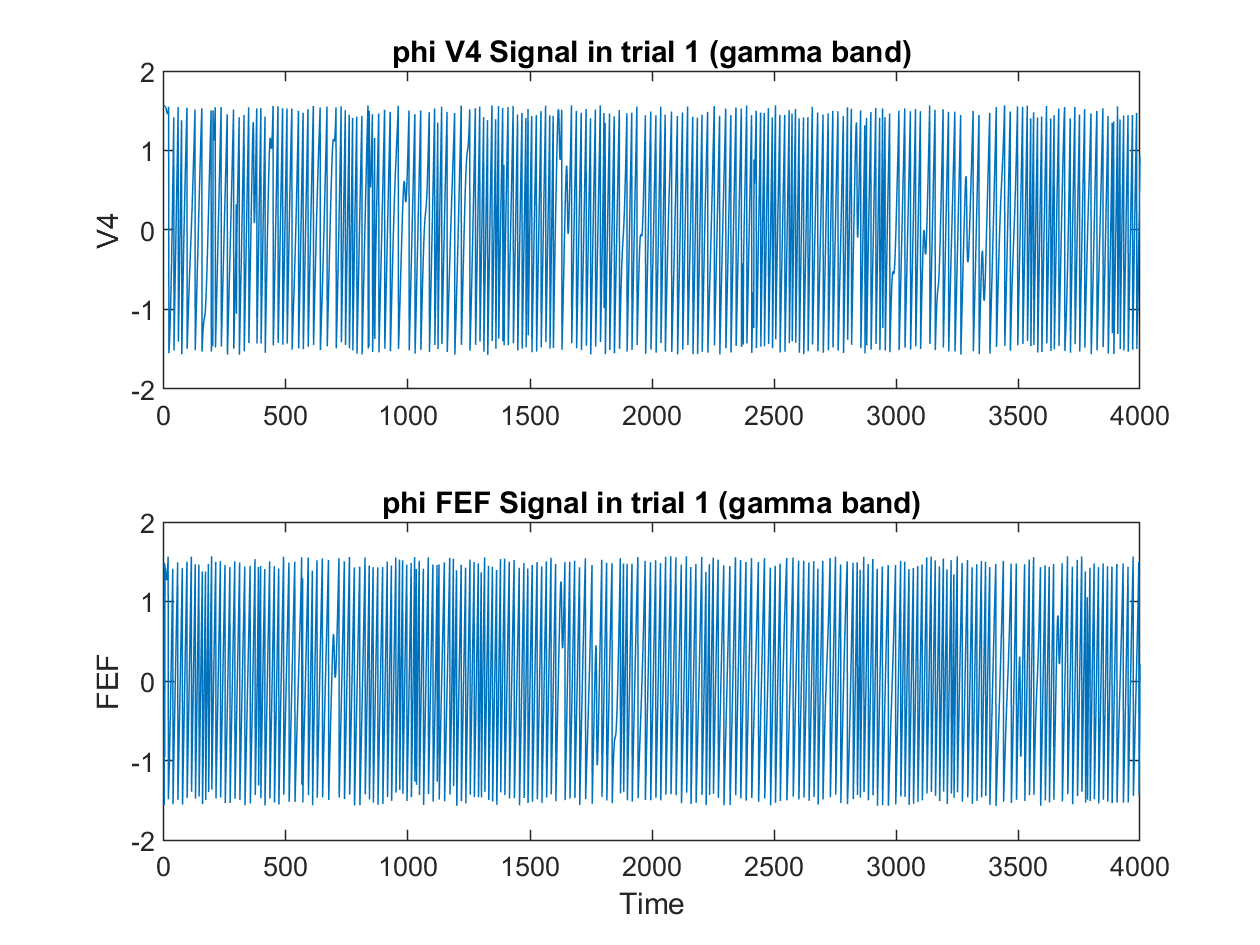

tiledlayout(2,1);

% Top plot
ax1 = nexttile;
plot(ax1,PhaseAng_V4_gamma(1,:));
title(ax1,'phi V4 Signal in trial 1 (gamma band)');
ylabel(ax1,'V4');


% Bottom plot
ax2 = nexttile;
plot(ax2,PhaseAng_FEF_gamma(1,:));
title(ax2,'phi FEF Signal in trial 1 (gamma band)');
ylabel(ax2,'FEF');
xlabel(ax2, 'Time');

### Step 3) Calculating PLV at each time point

clear i;
for t = 1:time
    sum_delta = 0;
    sum_theta = 0;
    sum_alpha = 0;
    sum_beta = 0;
    sum_gamma = 0;
    for j= 1:cnt_trial
        sum_delta = abs(sum_delta + exp(i*((PhaseAng_V4_delta(j,t)) - (PhaseAng_FEF_delta(j,t)))));
        sum_theta = abs(sum_theta + exp(i*((PhaseAng_V4_theta(j,t)) - (PhaseAng_FEF_theta(j,t)))));
        sum_alpha = abs(sum_alpha + exp(i*((PhaseAng_V4_alpha(j,t)) - (PhaseAng_FEF_alpha(j,t)))));
        sum_beta = abs(sum_beta + exp(i*((PhaseAng_V4_beta(j,t)) - (PhaseAng_FEF_beta(j,t)))));
        sum_gamma = abs(sum_gamma + exp(i*((PhaseAng_V4_gamma(j,t)) - (PhaseAng_FEF_gamma(j,t)))));
    end
    PLV_delta(1,t) = (1/cnt_trial) * sum_delta;
    PLV_theta(1,t) = (1/cnt_trial) * sum_theta;
    PLV_alpha(1,t) = (1/cnt_trial) * sum_alpha;
    PLV_beta(1,t) = (1/cnt_trial) * sum_beta;
    PLV_gamma(1,t) = (1/cnt_trial) * sum_gamma;
end

#### PLV plot of delta band before baseline Normalization

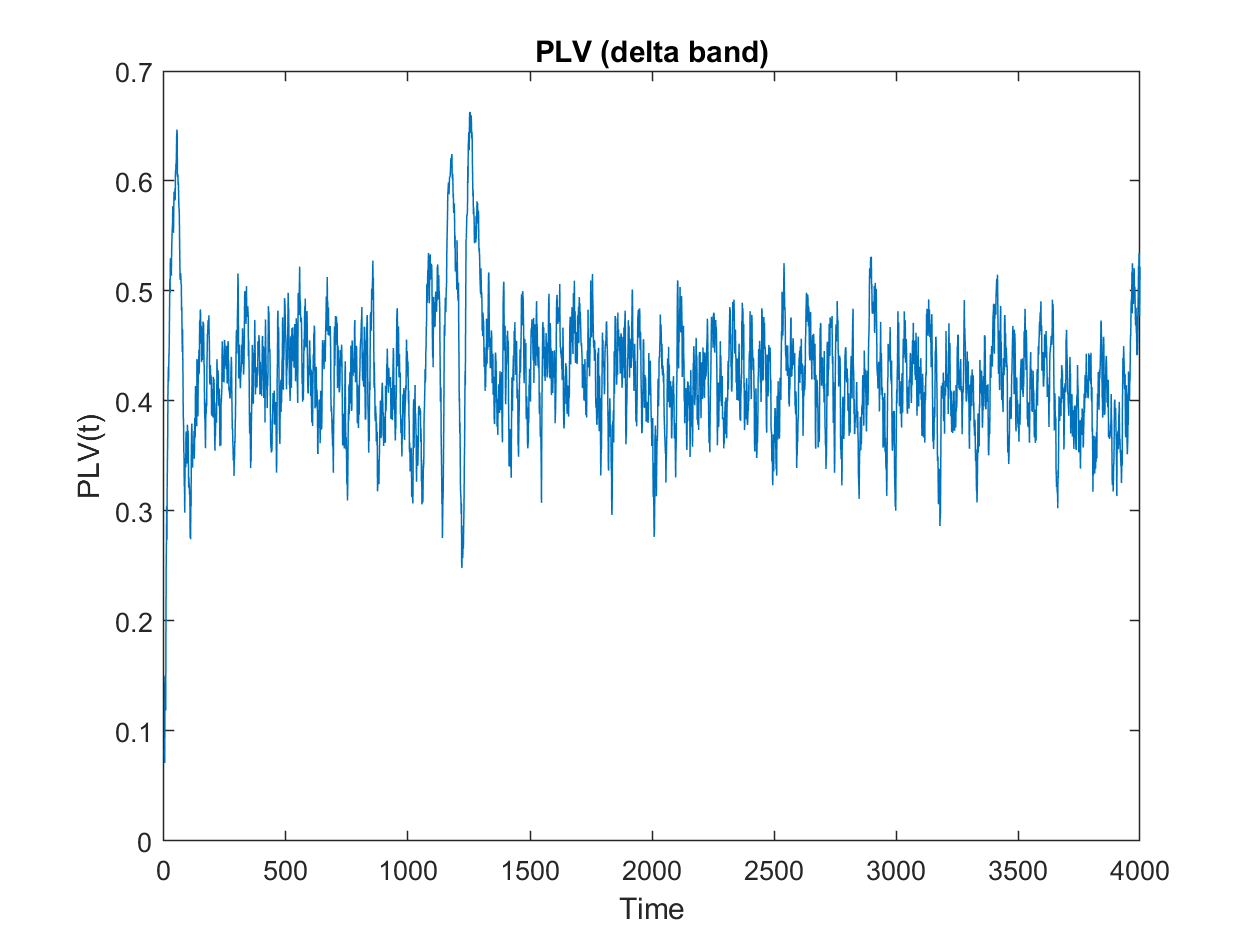

figure;plot(PLV_delta);
title("PLV (delta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

#### PLV plot of theta band before baseline Normalization

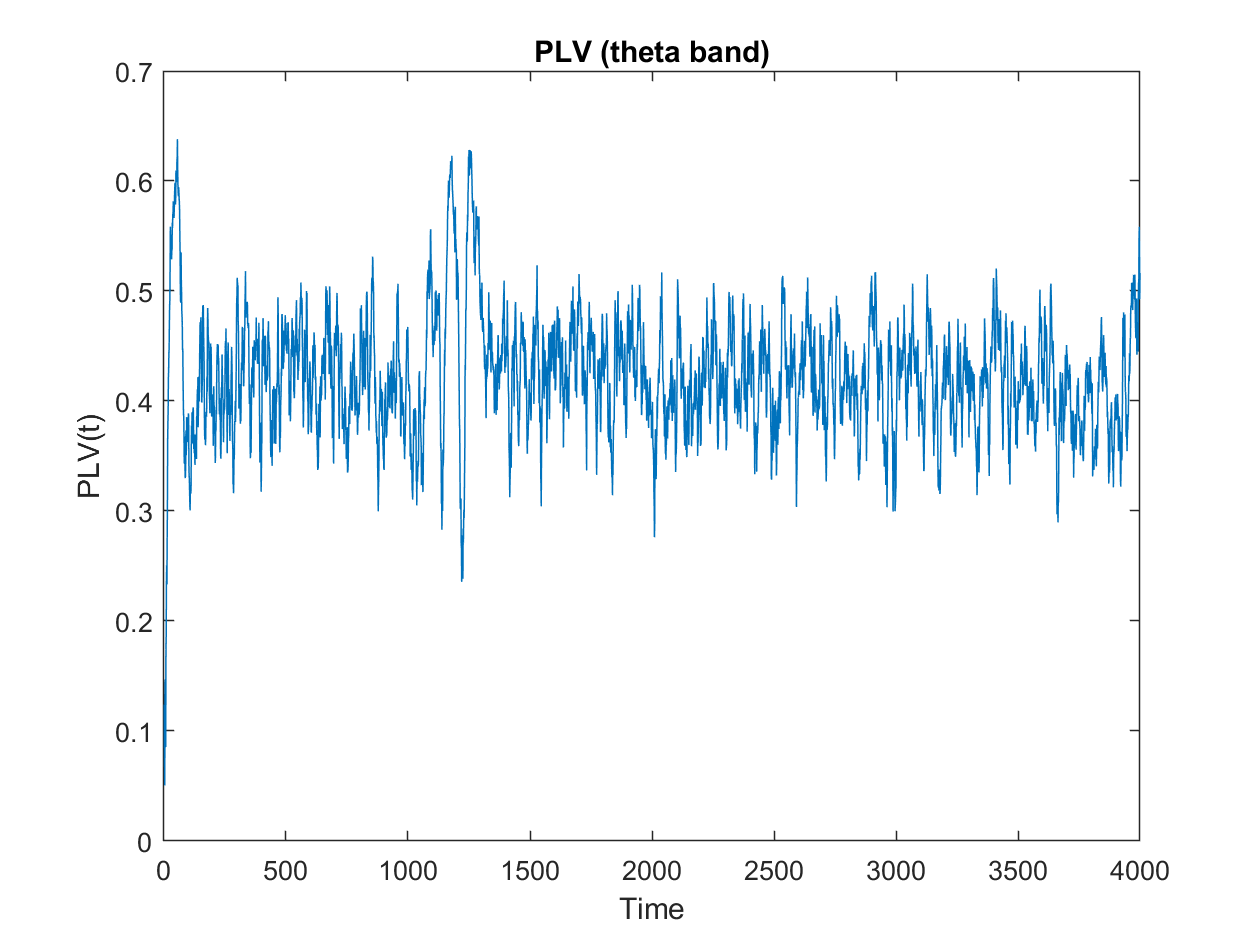

figure;plot(PLV_theta);
title("PLV (theta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

#### PLV plot of alpha band before baseline Normalization

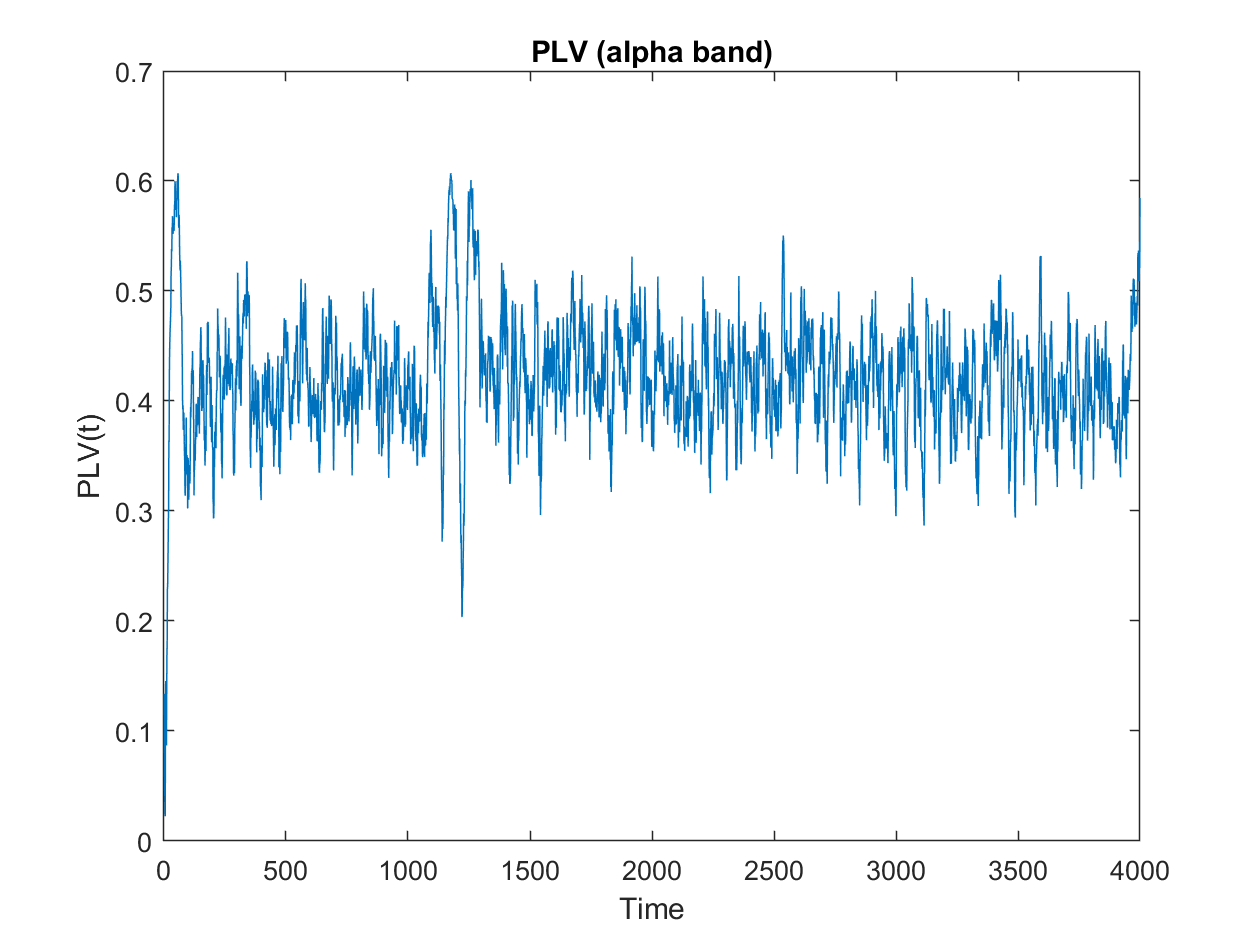

figure;plot(PLV_alpha);
title("PLV (alpha band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

#### PLV plot of beta band before baseline Normalization

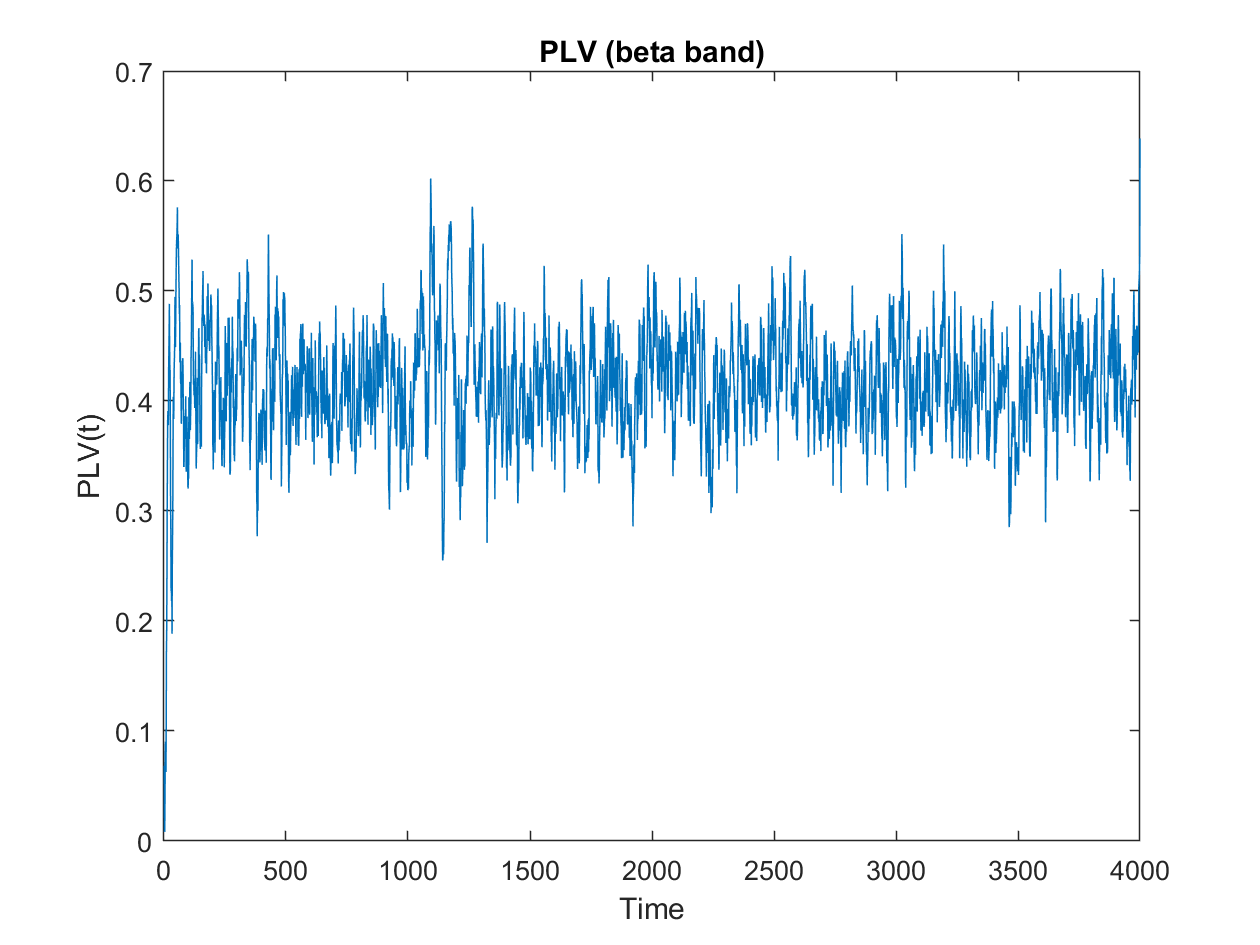

figure;plot(PLV_beta);
title("PLV (beta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

#### PLV plot of gamma band before baseline Normalization

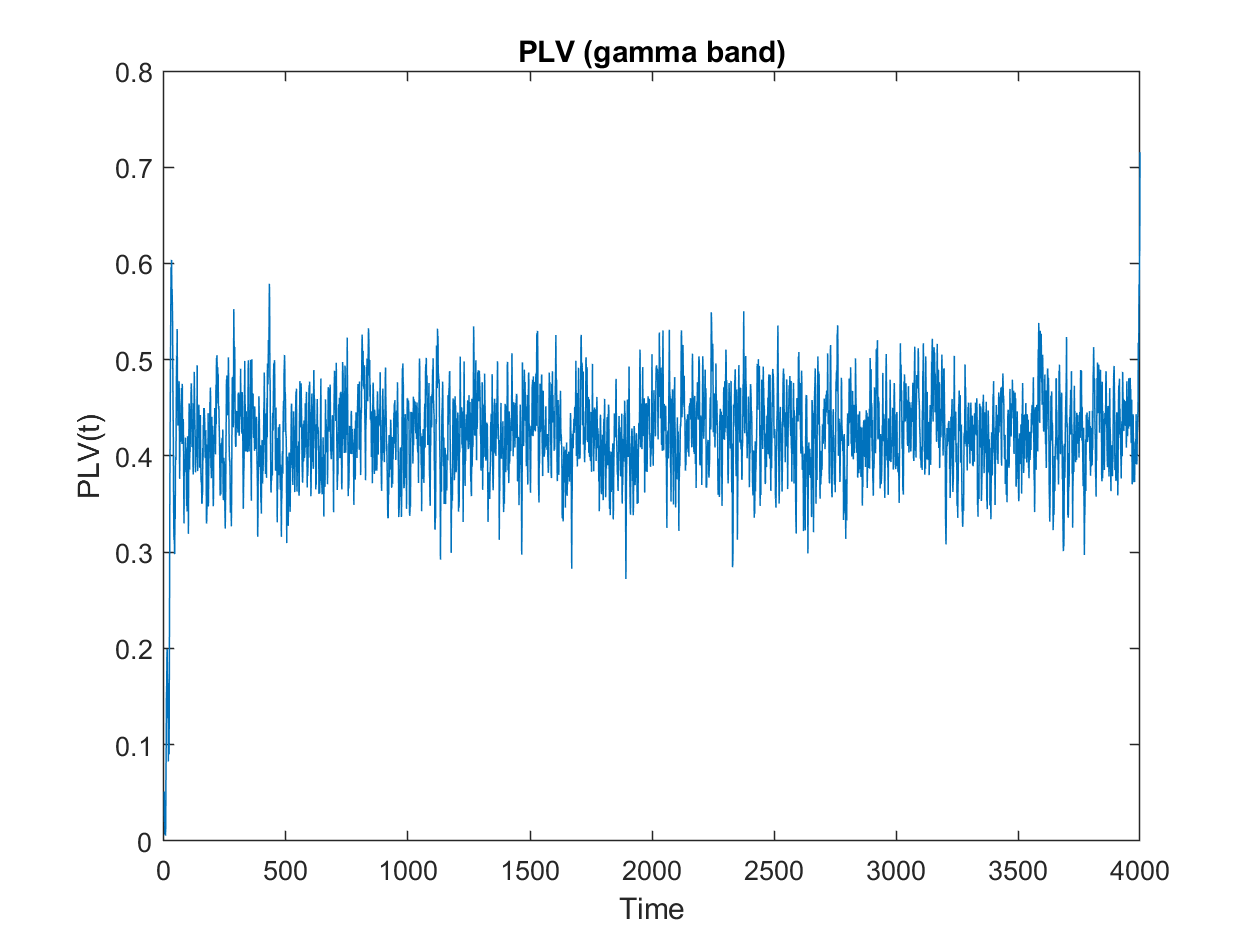

figure;plot(PLV_gamma);
title("PLV (gamma band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

### Step 4) baseline Normalization

norm_PLV_delta = (PLV_delta-mean(PLV_delta))/(sqrt(var(PLV_delta)));
norm_PLV_theta = (PLV_theta-mean(PLV_theta))/(sqrt(var(PLV_theta)));
norm_PLV_alpha = (PLV_alpha-mean(PLV_alpha))/(sqrt(var(PLV_alpha)));
norm_PLV_beta = (PLV_beta-mean(PLV_beta))/(sqrt(var(PLV_beta)));
norm_PLV_gamma = (PLV_gamma-mean(PLV_gamma))/(sqrt(var(PLV_gamma)));

#### PLV plot after baseline Normalization

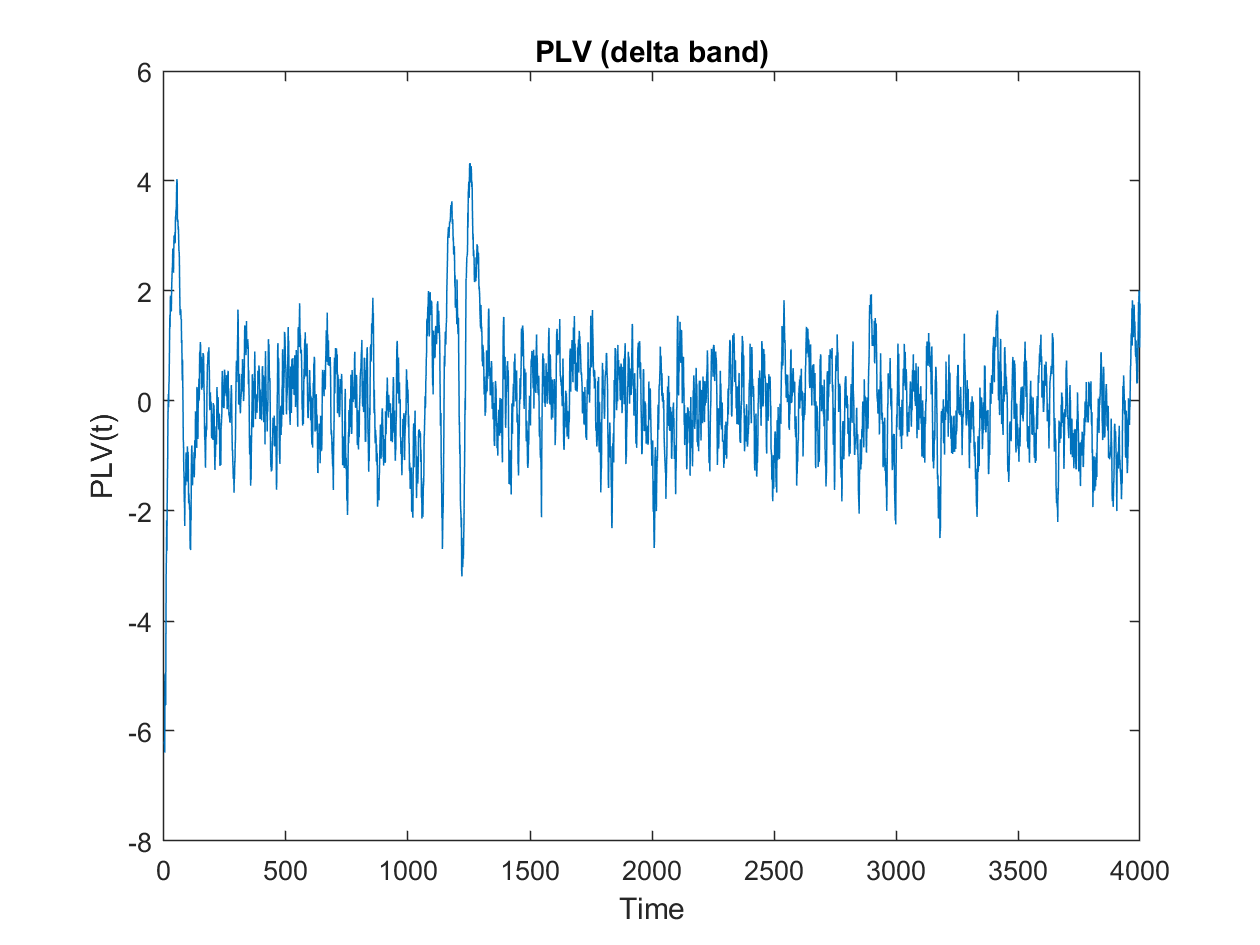


figure;plot(norm_PLV_delta);
title("PLV (delta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

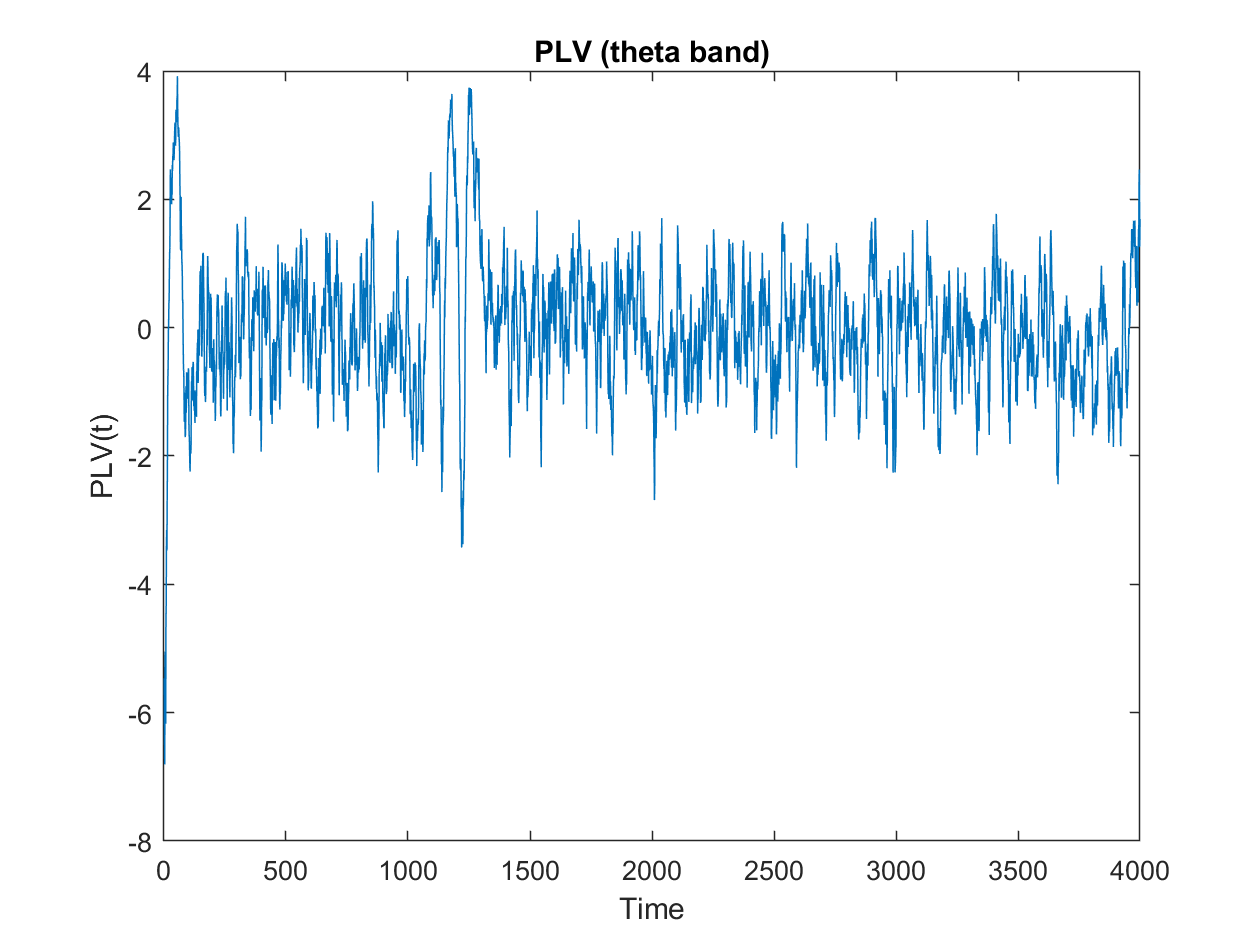


plot(norm_PLV_theta);
title("PLV (theta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

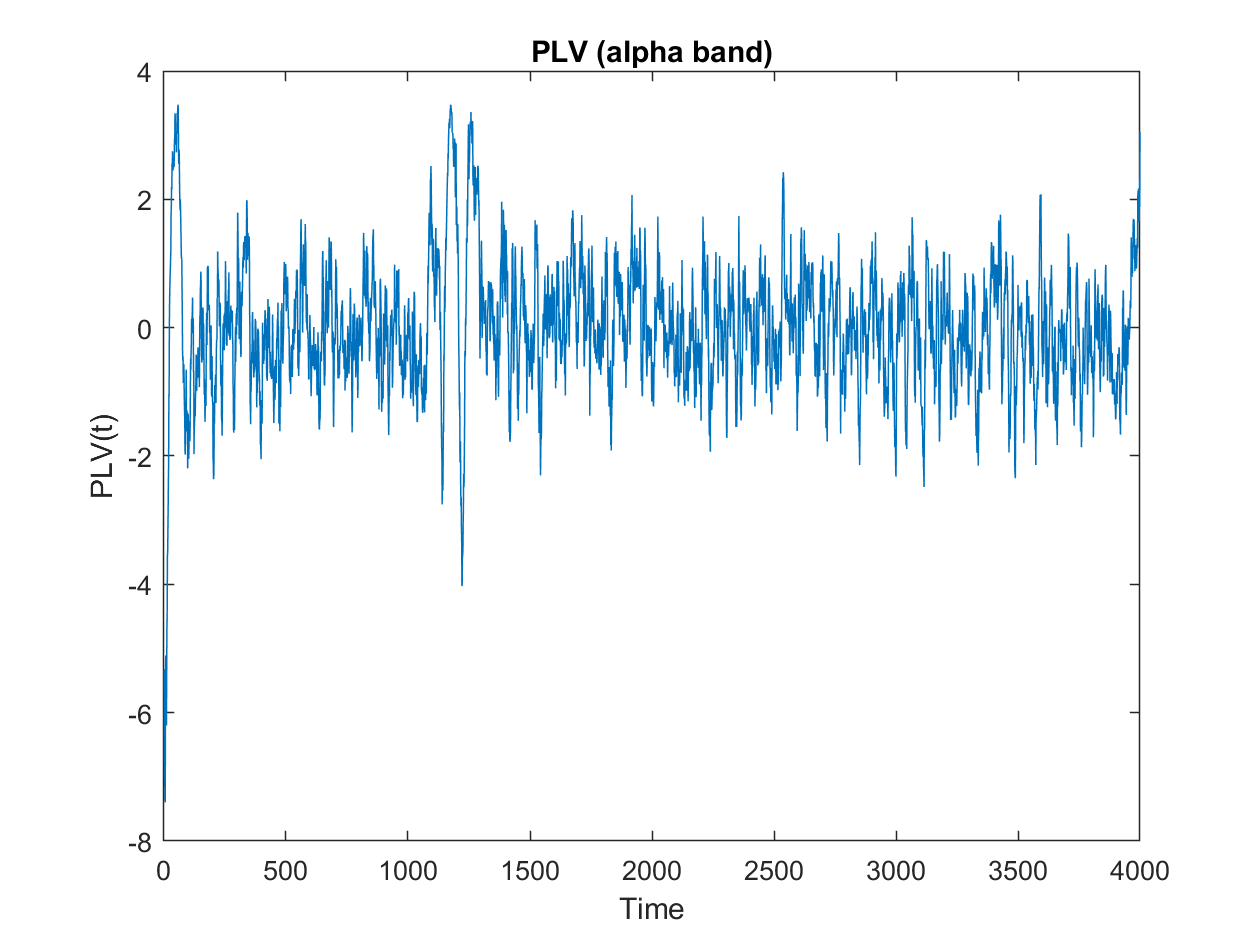


plot(norm_PLV_alpha);
title("PLV (alpha band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])

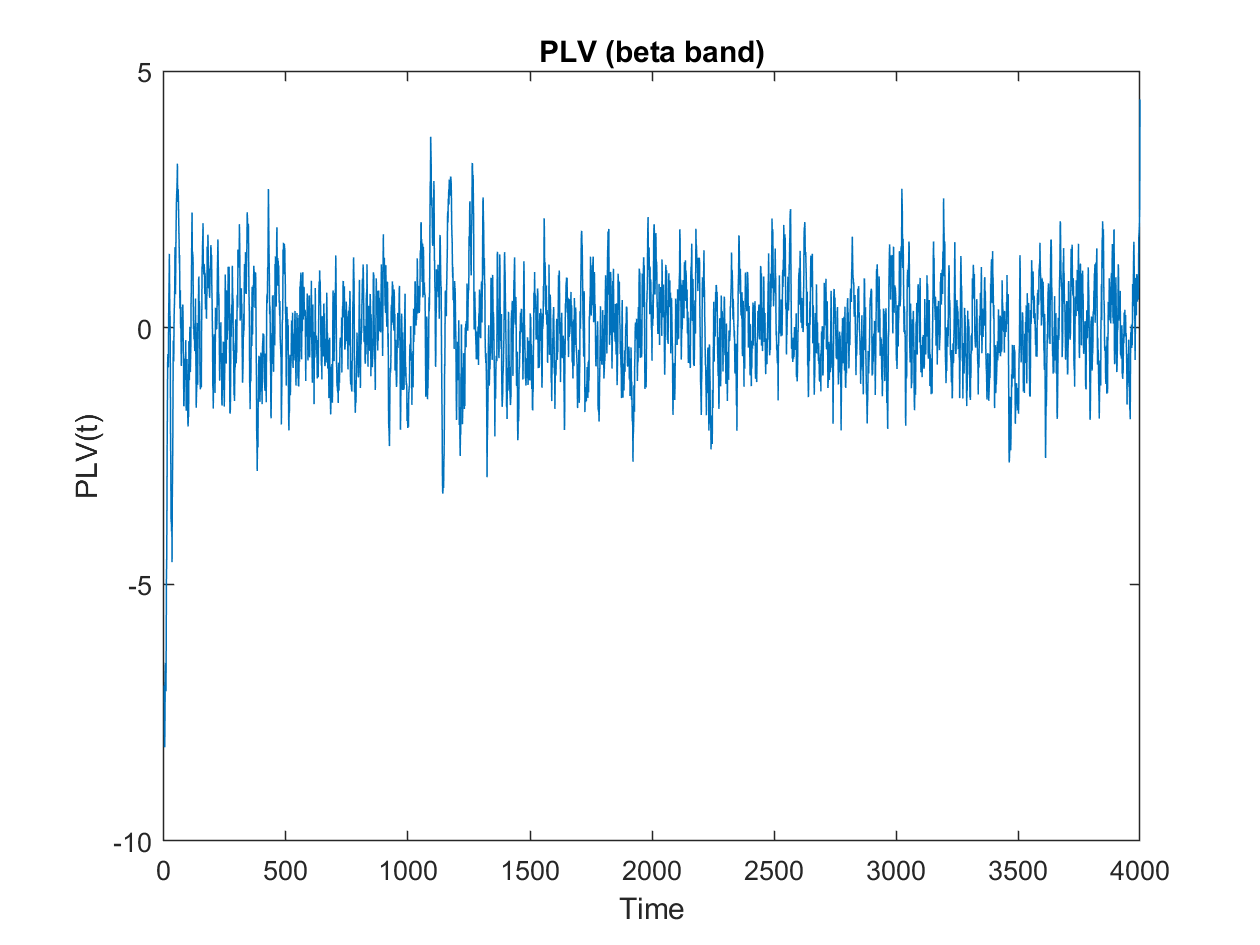


plot(norm_PLV_beta);
title("PLV (beta band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])


plot(PLV_gamma);
title("PLV (gamma band)")
xlabel('Time')
ylabel('PLV(t)')
xlim([0 4000])
hold off

**(e) **